# Homework 4

In this 4th homework, we will implement the algorithm described by Andrew Y. Ng, Michel I. Jordan and Yair Weiss in *"On Spectral Clustering: Analysis and an algorithm"*. This algorithm is based tools from Matrix Perturbation ([Eigenvalue Pertubation](https://en.wikipedia.org/wiki/Eigenvalue_perturbation)).

As always, we need to upload the data first of all:

data_1 = readmatrix("data_1.dat");
data_2 = readmatrix("data_2.dat");

## Step 1

After reading the data, we need to form the affinity matrix for both data. It is described as the first step in the paper.

- **Form the affinity matrix **$A\in \Re^{n\times n}$**defined by **$A_{\textrm{ij}} =e^{-\frac{{\left\|s_i -s_j \right\|}^2 }{2\sigma^2 }}$**if **$i\not= j$**, and **$A_{\textrm{ij}} =0$**.**

Due to Matlab limitations, the functions it is described at the end of the file. Basically, we 

affinity_matrix_1 = create_affinity_matrix(data_1);
affinity_matrix_2 = create_affinity_matrix(data_2);

Now that we have created the affinity matrix, we can already see some of our data divided in pairwise points. Let's visualize it:

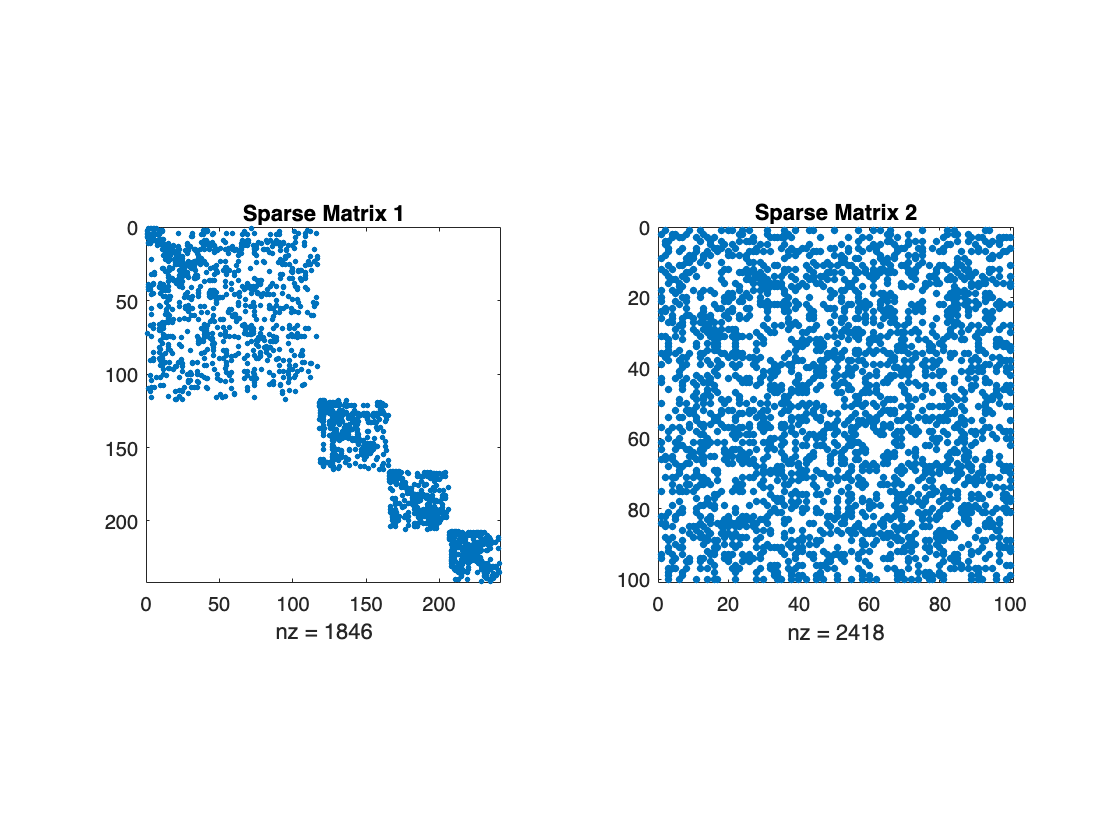

figure(1)
tiledlayout(1,2);
% Data 1
nexttile
spy(affinity_matrix_1);
title("Sparse Matrix 1")

% Data 2
nexttile
spy(affinity_matrix_2);
title("Sparse Matrix 2")

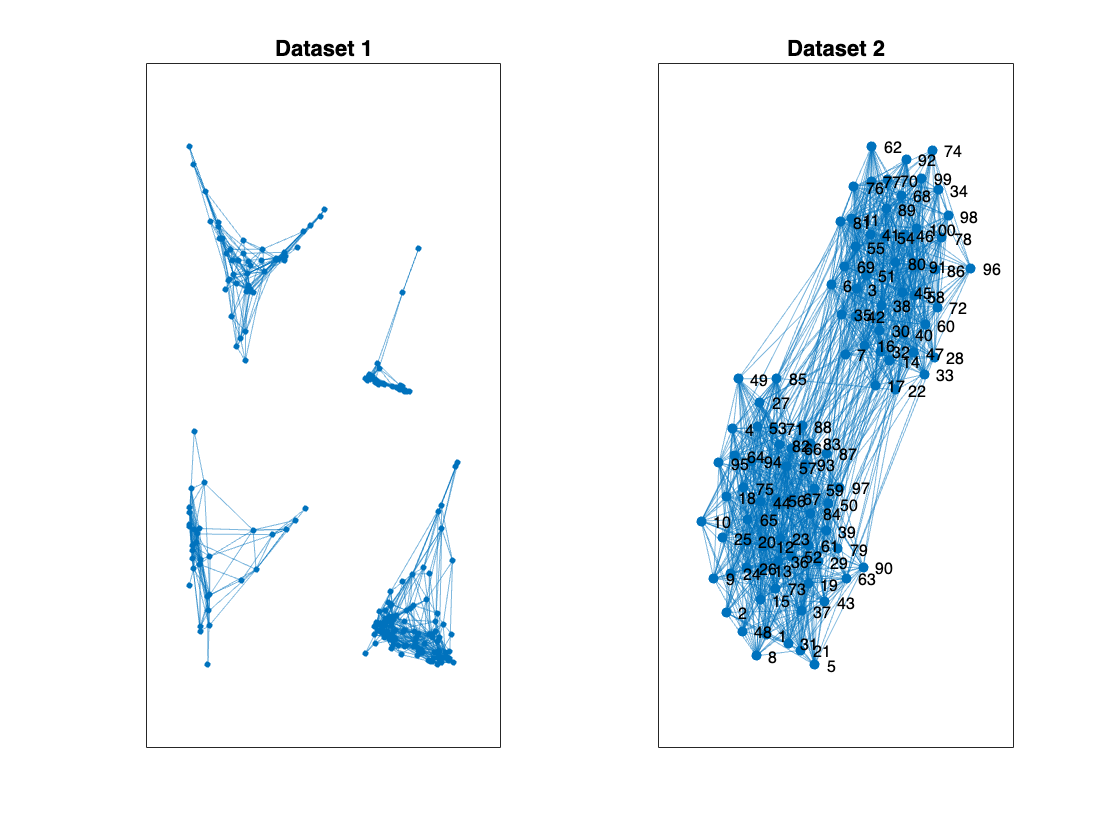

figure(2)
tiledlayout(1,2);
% Data 1
nexttile
plot_graph_1 = plot(graph(affinity_matrix_1), 'Layout','auto');
title("Dataset 1")

% Data 2
nexttile 
plot_graph_2 = plot(graph(affinity_matrix_2), 'Layout', 'auto');
title("Dataset 2")

There a few things which are worth to mention before continuing forward. In the first dataset, there is clearly 4 clusters which can be seen in both graphs, so it is obvious to think that we will find 4 important eigenvalues.

In the case of the second dataset, this is not that obvious. By just looking in the first plot, we cannot see anything clear. However, by looking at the graph, we can see that there are 2 main clusters which are somehow related. This connections could explain why is not clear the affinity matrix (although if we look at the diagonal starting from the top left to bottom right, we can see a sort of a line if we follow the white spots).

## Step 2

As the second step for the algorithm we need to create the diagonal matrix as follows:

**2. Define D to be the diagonal matrix whose (i,i)-element is the sum of A's i-th row, and construct the matrix **$L=D^{-\frac{1}{2}} {\textrm{AD}}^{-\frac{1}{2}}$**.**

diagonal_matrix_1 = get_diagonal_matrix(affinity_matrix_1);
diagonal_matrix_2 = get_diagonal_matrix(affinity_matrix_2);

## Step 3

In this step we just need to find the eigenvalues of the diagonal matrix found before:

**3. Find **$x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_k$**, the k largest eigenvectors of L (chosen to be ortogonal to each other in the case of repeated eigenvalues), and form the matrix **$X=\left\lbrack x_1 x_2 \ldotp \ldotp \ldotp x_k \right\rbrack \in \Re^{n\times k}$**by stacking the eigenvectors in columns.**

Before we have discussed about the number of cluster in each dataset. For the first dataset, we had 4 main clusters, and in the second dataset, only 2.

num_clusters_1 = 4;
num_clusters_2 = 2;

[eigenvalues_matrix_1, eigenvectors_matrix_1] = eigs(affinity_matrix_1, num_clusters_1);
[eigenvalues_matrix_2, eigenvectors_matrix_2] = eigs(affinity_matrix_2, num_clusters_2);

## Step 4

Now we normalize the eigenvalues.

**4. Form the matrix **$Y$**from **$X$ **by renormalizing each of **$X$**'s rows to have unit length (i.e. **$Y_{\textrm{ij}} =\frac{X_{\textrm{ij}} }{{\left(\sum X_{\textrm{ij}}^2 \right)}^{\frac{1}{2}} }$**)**

V_1 = eigenvalues_matrix_1;
V_2 = eigenvalues_matrix_2;

Y_1 = V_1./sum(V_1.*V_1,2).^(1/2);
Y_2 = V_2./sum(V_2.*V_2,2).^(1/2);

## **Step 5**

Using the K-Means algorithm we can get the different clusters based on the number of cluster that we have previously discussed in each case.

**5. Treating each row of **$Y$**as a point in **$\Re^k$**, cluster them into k clusters via K-means or any other algorithm (that attemps to minimize distortion).**

clusters_1 = kmeans(Y_1, num_clusters_1);
clusters_2 = kmeans(Y_2, num_clusters_2);

## **Step 6**

Finally, it is easy to see that we can divide the different clusters with certain precision.

**6. Finally, assign the original point **$s_i$**to cluster **$j$** if and only if row **$i$ **of the matrix **$Y$**was assigned to cluster **$j$**.**

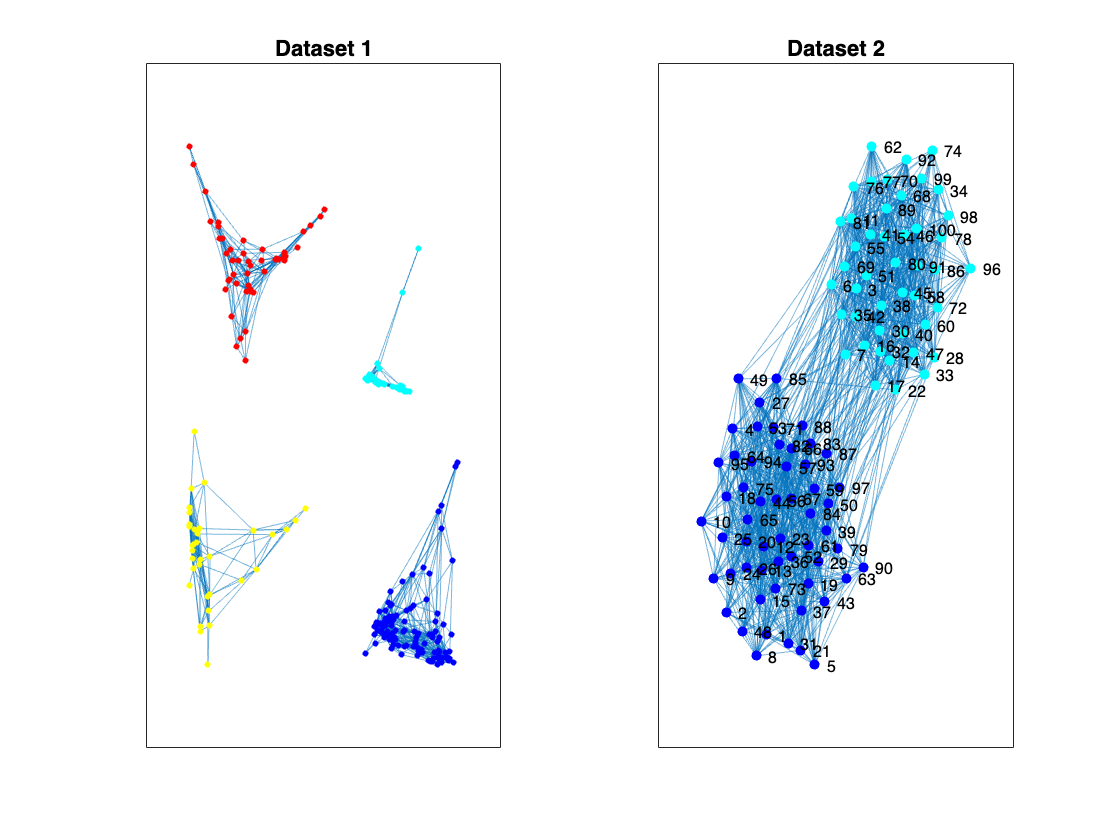

clusters_colors_1 = jet(num_clusters_1);
clusters_colors_2 = jet(num_clusters_2);

for i=1:num_clusters_1
    cluster_members_1 = find(clusters_1==i);
    highlight(plot_graph_1, cluster_members_1, 'NodeColor', clusters_colors_1(i,:));
end

for i=1:num_clusters_2
    clusters_members_2 = find(clusters_2==i);
    highlight(plot_graph_2, clusters_members_2, 'NodeColor', clusters_colors_2(i,:));
end

## Connectivity

As a final part, we would like to see the Fiedler value, which is the second smallest value eigenvalue of the Laplacian matrix. If it is greater than 0 we can say the the graph is connected.

D_1 = diag(sum(affinity_matrix_1,2));
D_2 = diag(sum(affinity_matrix_2,2));
denormalized_lagrange_1 = D_1 - affinity_matrix_1;
denormalized_lagrange_2 = D_2 - affinity_matrix_2;
[denormalized_fiedler_values_1, ~] = eigs(denormalized_lagrange_1, 2, 'smallestreal');

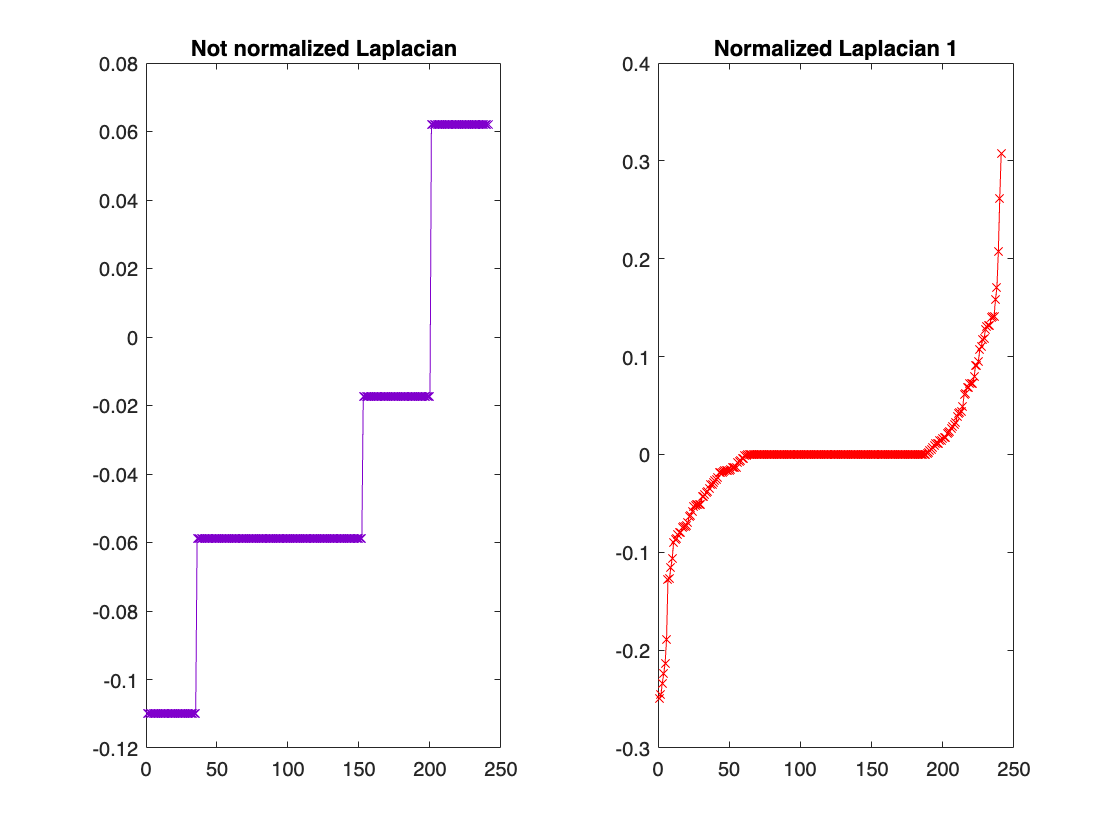

[denormalized_fiedler_values_2, ~] = eigs(denormalized_lagrange_2, 2, 'smallestreal');
[fiedler_values_1, ~] = eigs(diagonal_matrix_1, 2, 'smallestreal');
[fiedler_values_2, ~] = eigs(diagonal_matrix_2, 2, 'smallestreal');

figure(3);
tiledlayout(1,2);
nexttile
plot(sort(denormalized_fiedler_values_1(:,2)), '-x', 'Color',[0.5 0 0.8]);
title("Not normalized Laplacian")
nexttile
plot(sort(fiedler_values_1(:,2)), '-x','Color','red');
title("Normalized Laplacian 1")

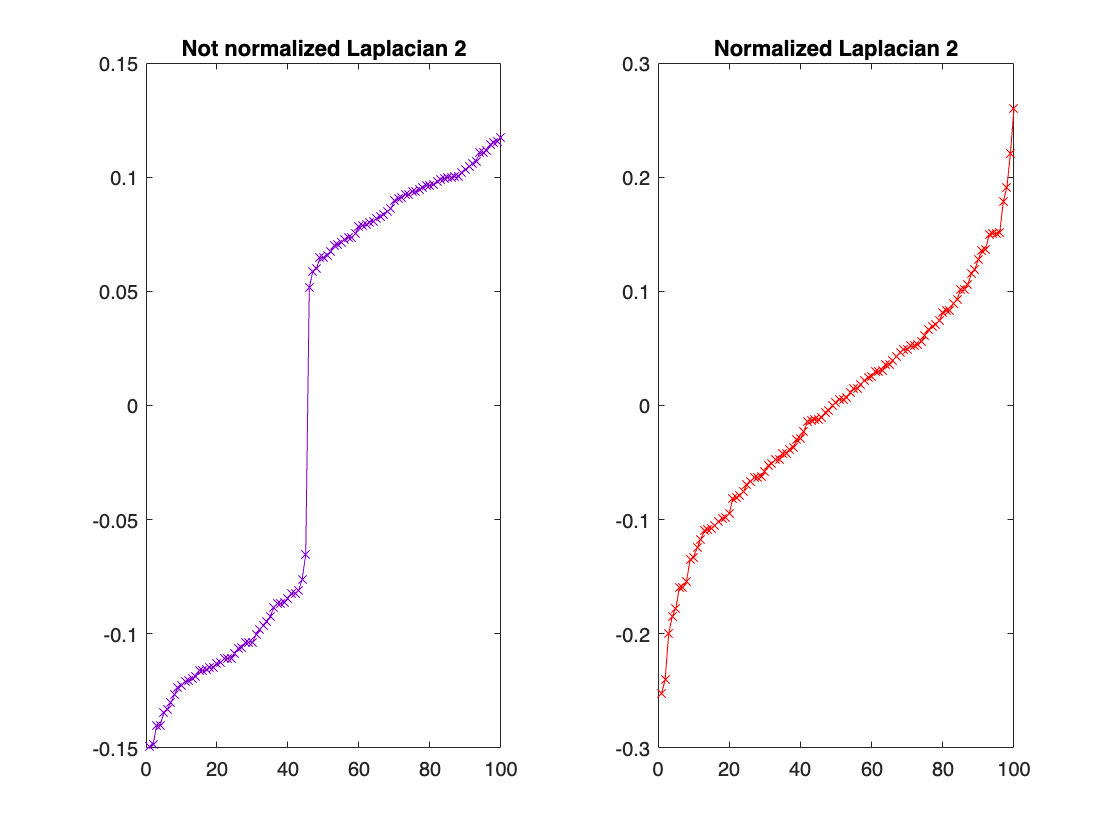

figure(4);
tiledlayout(1,2);
nexttile
plot(sort(denormalized_fiedler_values_2(:,2)), '-x', 'Color',[0.5 0 0.8]);
title("Not normalized Laplacian 2")
nexttile
plot(sort(fiedler_values_2(:,2)), '-x','Color','red');
title("Normalized Laplacian 2")

function affinity_matrix = create_affinity_matrix(data)
    col1 = data(:,1);
    col2 = data(:,2);
    max_ids = max(max(col1, col2));
    As = sparse(col1, col2, 1, max_ids, max_ids);
    affinity_matrix = full(adjacency(graph(As))); % If only full( ) it gives problem in the not normalized laplacian
end

function diagonal_matrix = get_diagonal_matrix(affinity_matrix)
    D = diag(sum(affinity_matrix,2)); % (i,i)-element sum
    diagonal_matrix = (D^(-1/2)*affinity_matrix*D^(-1/2));
end

